# **EllipticE**

Complete and incomplete Jacobi form of the elliptic integral of the second kind 

## Definition 

**Incomplete elliptic integral of the second kind**


$$\mathit{\mathbf{E}}\left(x\left|m\right.\right)\equiv \int_0^x \sqrt{\frac{1-m\;t^2 }{1-t^2 }}\;\mathit{dt}$$



$$\mathit{\mathbf{E}}\left(x,k\right)\equiv \mathit{\mathbf{E}}\left(x\left|k^2 \right.\right)$$


Domain: $1-x^2 \ge 0$ and $1-mx^2 \ge 0$. If $-\infty <m\le 1$  (or $|k|\le 1$) then $-1\le x\le 1$. If $m>1$ (or $k>1$) then  $|x|<1/\sqrt{m}$. For the specified domain, the  codomain  is real numbers.

Basic features:

$\mathit{\mathbf{E}}\left(-x\left|m\right.\right)=-\mathit{\mathbf{E}}\left(x\left|m\right.\right)$   (odd)

Special values:

$\mathit{\mathbf{E}}\left(0\left|m\right.\right)=0$,   $\mathit{\mathbf{E}}\left(1\left|m\right.\right)=E\left(m\right)$

$\mathit{\mathbf{E}}\left(x\left|0\right.\right)=\sin^{-1} \left(x\right)$,   $\mathit{\mathbf{E}}\left(x\left|1\right.\right)=x$

Identities:


$$\mathit{\mathbf{E}}\left(x\left|m\right.\right)=E\left(\sin^{-1} \left(x\right)\left|m\right.\right),\;\;\;\;\mathit{\mathbf{E}}\left(x|m\right)=\epsilon \left({\mathrm{sn}}^{-1} \left(x|m\right)|m\right),\;\;\;\;\left|x\right|\le 1$$


$E\left(\phi \left|m\right.\right)$ is Legendre form of the elliptic integral of the second kind, $\epsilon \left(u\left|m\right.\right)$ is Jacobi's second form of the elliptic integral of the second kind.

**Complete elliptic integral of the second kind**


$$E\left(m\right)\equiv \mathit{\mathbf{E}}\left(1\left|m\right.\right)=E\left(\frac{\pi }{2}\left|m\right.\right)$$



$$\mathit{\mathbf{E}}\left(k\right)\equiv E\left(k^2 \right)$$


where *k *is the modulus, *m *is the parameter.

Domain: $1-m\ge 0$, (or $|k|\le 1$). For the specified domain, the  codomain is real numbers.

Special values:

$E\left(-\infty \right)=\infty ,$   $E\left(0\right)=\frac{\pi }{2}$,   $E\left(1\right)=1$

## Syntax

**Incomplete integral**

Y = EllipticE(X,K)

y = elE(x,k)

Y = mEllipticE(X,M)

y = melE(x,m)

**Complete integral**

Y = EllipticE(K)

y = elE(k)

Y = mEllipticE(M)

y = melE(m)

## Description

**Incomplete integral**

**Y = EllipticE(X,K)** returns the Jacobi form of elliptic integral of the second kind $\mathit{\mathbf{E}}\left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be scalar. **EllipticE** is the wrapper function which calls the functions **elE** element-wise via the function **ufun2**.

**y = elE(x,k)** returns  value of the Jacobi form of elliptic integral of the second kind  $\mathit{\mathbf{E}}\left(x,k\right)$ for argument *x* and the modulus k. It is assumed that the input arguments are real scalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. **elE** is the wrapper function which calls the functions **melE**.

**Y = mEllipticE(X,M) **returns the Jacobi form of elliptic integral of the first kind $\mathit{\mathbf{E}}\left(x\left|m\right.\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be scalar. **mEllipticE** is the wrapper function which calls the functions **melE** element-wise via the function **ufun2**.

**y = melE(x,m)** compute the value of the Jacobi form of elliptic integral of the first kind  $\mathit{\mathbf{E}}\left(x\left|m\right.\right)$ for  argument x and the parameter m. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **melE **call the Carlson's functions **rf **and** rd **for calculation of $\mathit{\mathbf{E}}\left(x\left|m\right.\right)$ ([1-2]).

**Complete integral**

**Y = EllipticE(K) **returns the value of the complete elliptic integral of the second kind $\mathit{\mathbf{E}}\left(k\right)$ for each element of the array  K (modulus).  K must be real array or scalar. **EllipticE** is the wrapper function which calls the functions **elE** element-wise via the function **ufun1**.

**y = elE(k)** returns the value of the complete elliptic integral of the second kind  $\mathit{\mathbf{E}}\left(k\right)$ for  the modulus k. It is assumed that  k is real scalars without check. y is NaN if k is invalid or convergence failed. **elE** is the wrapper function which calls the functions **melE**.

**Y = mEllipticE(M)** returns the value of  the complete elliptic integral of the second kind $E\left(m\right)$ for each element of the array  M (parameter).  M must be real array or scalar. **mEllipticE** is the wrapper function which calls the functions **melE** element-wise via the function **ufun1**.

**y = melE(m)** compute value of  the complete elliptic integral of the second kind $E\left(m\right)$ for  the parameter m. It is assumed that  m is real scalars without check. y is NaN if m is invalid or convergence failed.  **melE **call the function **mcelE **which call the Carlson's functions **rg** for calculation of $E\left(m\right)$ ([1-2]).

## Precision

For $-{10}^6 <m<1$ the relative error of **mcelE  **is less than ${10}^{-12}$ .  

## **Numerical Examples**

**Scalar input**

format long
k = 0.5; % |k|<= 1
x = 0.5;
[elE(x,k), EllipticE(x,k), melE(x,k^2), mEllipticE(x,k^2)]

ans =    0.517881934859938   0.517881934859938   0.517881934859938   0.517881934859938


[elE(k), EllipticE(k), melE(k^2), mEllipticE(k^2)]

ans =    1.467462209339427   1.467462209339427   1.467462209339427   1.467462209339427


m = 0.5; % |m|<1 
[elK(sqrt(m)), EllipticK(sqrt(m)), melK(m), mEllipticK(m)]

ans =    1.854074677301372   1.854074677301372   1.854074677301372   1.854074677301372


From Maple documentation

fprintf('%.10g\n',elE(0.2,0.3)) % .2012363833

0.2012363833


fprintf('%.10g\n',elE(0.3)) % 1.534833465

1.534833465


Accuracy. 

fprintf('%.16g\n',elE(0.5,1.2)) % Maple 18D   0.4889133506831121 18

0.4889133506831121


fprintf('%.16g\n',melE(-4)) % Maple 18D   2.63518358159563 009

2.63518358159563


Special values

m = -2;
x = -0.5;  % |x| <= 1
melE(0,m)

ans = 0

disp(melE(1,m) - melE(m))  % m < 1 !!!

     0



melE(x,-inf)

ans = -Inf

disp(melE(x,0) - asin(x))

     0



disp(melE(x,1) - x)

     0



melE(x,-inf)  

ans = -Inf

melE(-inf)

ans = Inf

disp(elE(0) - pi/2)

     0



disp(elE(1)-1)

     0



Identities

m = -2;
x = 0.5; % |x| <= 1
mEllipticE(-x,m) + mEllipticE(x,m)

ans = 0

disp(mEllipticE(x,m) - mpEllipticE(asin(x),m))

    -1.110223024625157e-16



m = -2;
disp(melE(x,m) - mjepsilon(mijsn(x,m),m))

     2.220446049250313e-16



k = 0.99995;
disp(EllipticE(1/sqrt(1+sqrt(1-k^2)),k)-(elE(k) + 1 - sqrt(1 - k^2))/2)

    -2.886579864025407e-15



[MATLAB example](https://www.mathworks.com/help/symbolic/elliptice.html)

s = [mEllipticE(-10.5), mEllipticE(-pi/4),...
 mEllipticE(0),  mEllipticE(1)]

s =    3.709613909652783   1.844349246873229   1.570796326794897   1.000000000000000


**Vector input**

k = [ -1, 0.2, 0.99995]';
disp(EllipticE(1./sqrt(1+sqrt(1-k.^2)),k)-(EllipticE(k) + 1 - sqrt(1 - k.^2))./2)

   1.0e-14 *

                   0
   0.011102230246252
  -0.288657986402541



**Matrix input**

k = [ -1, 0.2, 0.99995; 0.5, 0.3, 0.6]';
disp(EllipticE(1./sqrt(1+sqrt(1-k.^2)),k)-(EllipticE(k) + 1 - sqrt(1 - k.^2))./2)

   1.0e-14 *

                   0                   0
   0.011102230246252  -0.022204460492503
  -0.288657986402541  -0.011102230246252



## **Plot **

**Example 1**

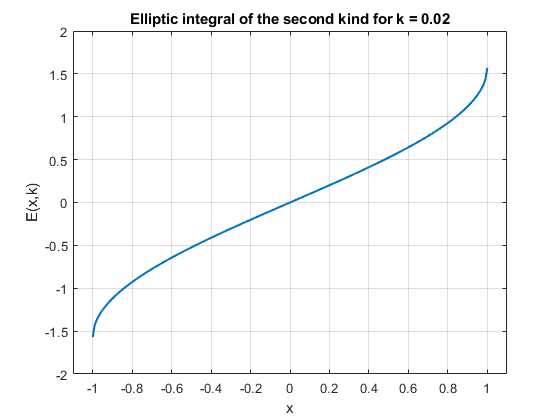

figure
x=-1:0.01:1;
k = 0.02;
plot(x,EllipticE(x,k),'LineWidth',1.5)
xlabel('x')
ylabel('E(x,k)')
xlim([-1.1 1.1])
%ylim([-3 3])
title(sprintf('Elliptic integral of the second kind for k = %g',k))
grid on

**Example 2**

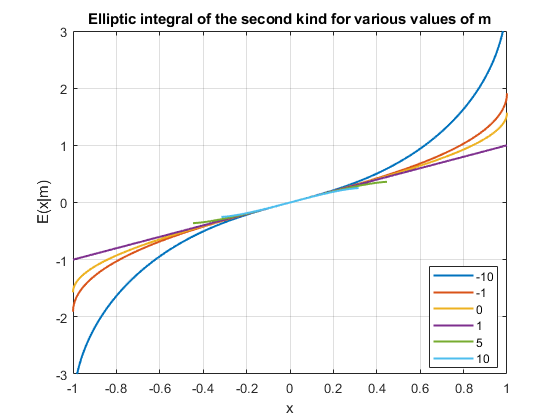

figure
X = -1:0.001:1;
M = [-10,-1,0,1,5,10];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mEllipticE(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) -3 3])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Elliptic integral of the second kind for various values of m')
xlabel('x')
ylabel('E(x|m)')

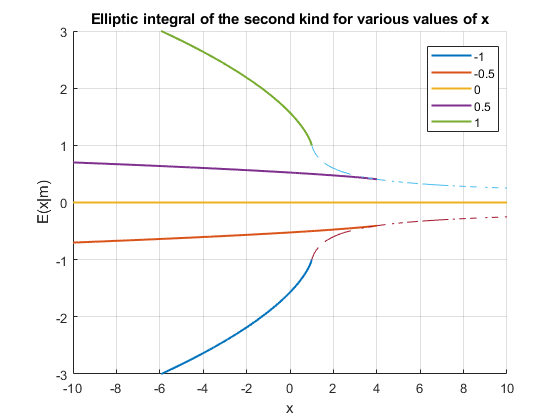

figure
hold on
M = -10:0.01:10;
X = [-1,-0.5,0,0.5,1];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mEllipticE(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) -3 3])
grid on
legend(clg{1:length(X)},'Location','Best')
title('Elliptic integral of the second kind for various values of x')
xlabel('x')
ylabel('E(x|m)')
M = 0:0.1:10;
E = mEllipticE(1./sqrt(abs(M)),M);
plot(M,E)
plot(M,-E)
hold off

**Example 3**

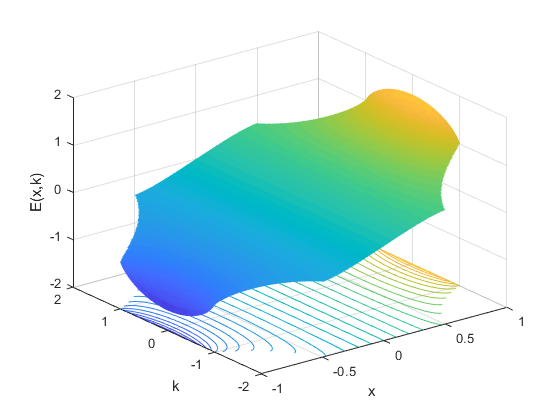

figure
x=-1:0.01:1;
k=-2:0.01:2;
[X,K]=meshgrid(x,k);
hs=surfc(X,K,EllipticE(X,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -2;
hc.LineWidth = 0.5;
hc.LevelList = -2:0.1:2;
caxis([-2 2])
view(3);
xlabel('x')
ylabel('k')
zlabel('E(x,k)')
zlim([-2 2])
grid on

**Example 4**

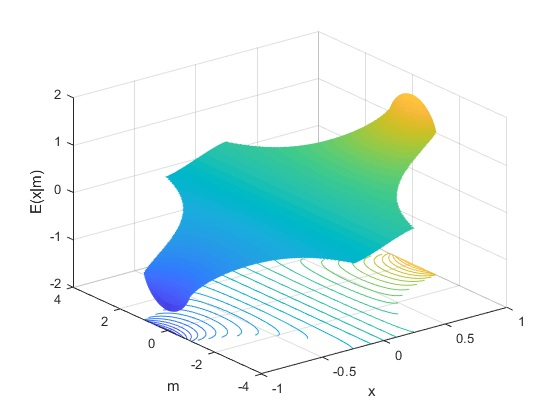

figure
x=-1:0.01:1;
m=-4:0.01:4;
[X,M]=meshgrid(x,m);
hs=surfc(X,M,EllipticE(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -2;
hc.LineWidth = 0.5;
hc.LevelList = -2:0.1:2;
view(3)
caxis([-2 2])
xlabel('x')
ylabel('m')
zlabel('E(x|m)')
zlim([-2 2])
grid on

**Example 5**

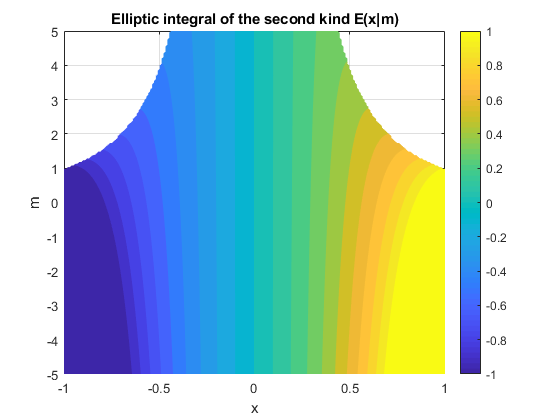

figure
f = @(x,m)mEllipticE(x,m);
fcontour(f,[-1 1 -5 5],'Fill','on','LevelList',-1:0.1:1,'MeshDensity',200)
title('Elliptic integral of the second kind E(x|m)')
xlabel('x')
ylabel('m')
colorbar
grid on

**Example 6**

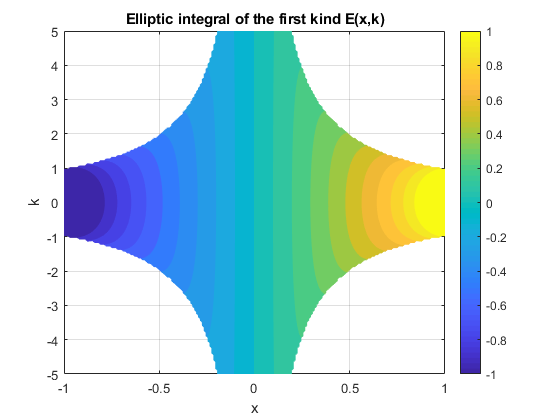

figure
f = @(x,k)EllipticE(x,k);
fcontour(f,[-1 1 -5 5],'Fill','on','LevelList',-1:0.1:1,'MeshDensity',200)
title('Elliptic integral of the first kind E(x,k)')
xlabel('x')
ylabel('k')
colorbar
grid on

**Example 7**

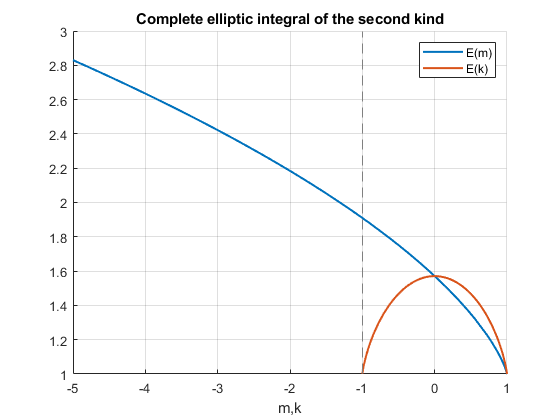

figure
hold on
fplot(@(m) mEllipticE(m),'LineWidth',1.5)
fplot(@(k) EllipticE(k),'LineWidth',1.5)
title('Complete elliptic integral of the second kind')
legend('E(m)','E(k)')
xlabel('m,k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

[Elliptic integrals, Wikipedia](https://en.wikipedia.org/wiki/Elliptic_integral)

## **References**

[1] B.C. Carlson, Computing Elliptic Integrals by Duplication. Numerische Mathematik 33, 1-16, 1979.

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

## See Also